clc
clear

dotQ=[1;2;3;4;5;6];
ke=100;
kp=10;
%initial value
Q=[0;0;0;0;0;0];
Qa=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
Qy=40;
%dt
elasticdt=0.005;
plasticdt=0.005/100;

if norm(Q(:,1))-Qy>0
else
    iflag=0;
end

for i=1:40000
    if iflag==0
        q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        if norm(Q(:,i+1))-Qy>0
            if Q(:,i+1)'*dotQ<0
                iflag=0;
                q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
                Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
                Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
            else
                iflag=1;
                i
                syms dt
                f=Q(:,i)+dotQ*dt;
                f1=norm(f)-Qy;
                dt1=solve(f1,dt);
                dt=double(dt1);
                aa=find (dt<0);
                dt(aa)=[];
                q(:,i+1)=q(:,i)+(dotQ/ke)*dt;
                Q(:,i+1)=Q(:,i)+dotQ*dt;%Qton
                Qa(:,i+1)=Qa(:,i)+dotQ*dt;
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+(Qa(:,i)'*dotQ*Qa(:,i)/(kp*Qy*Qy)+dotQ/ke)*plasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*plasticdt;
        Qa(:,i+1)=Qa(:,i)+(-Qa(:,i)'*dotQ*Qa(:,i)/(Qy*Qy)+dotQ)*plasticdt;
        if Q(:,i+1)'*dotQ<0
            iflag=0;
            q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
            Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
            Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        end
    end
    ik=0;
end

i = 839

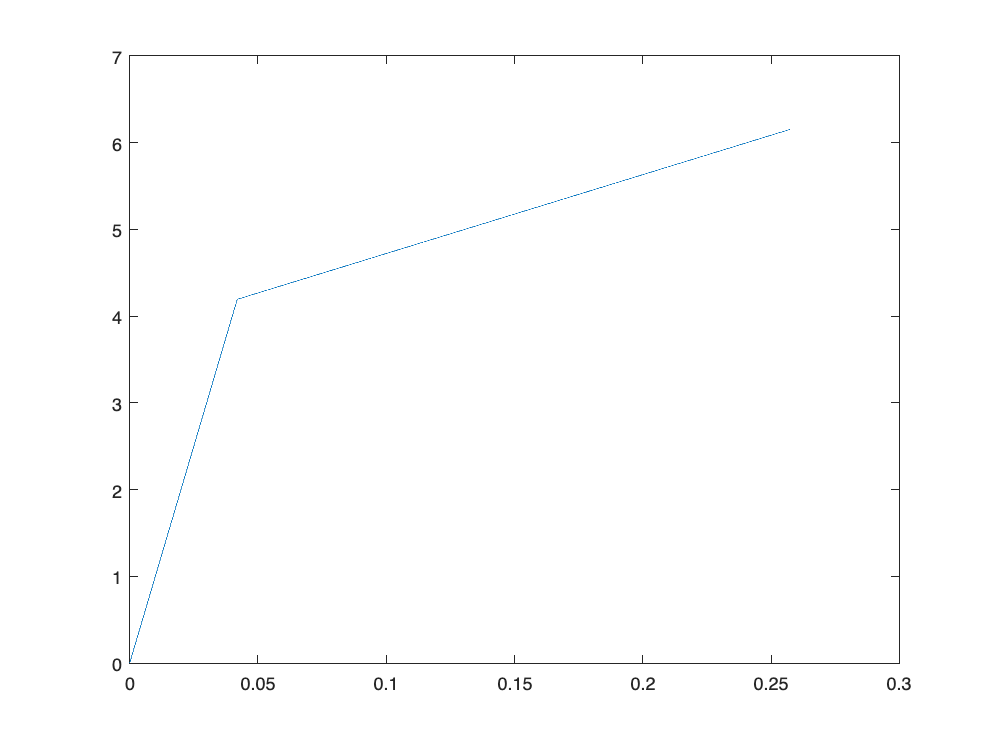

plot(q(1,:),Q(1,:))